# Lab 6

## Kurt Delegard

## PHYS 434 AB

### Time spent drafting: 

clear;
load('hera_data.mat')

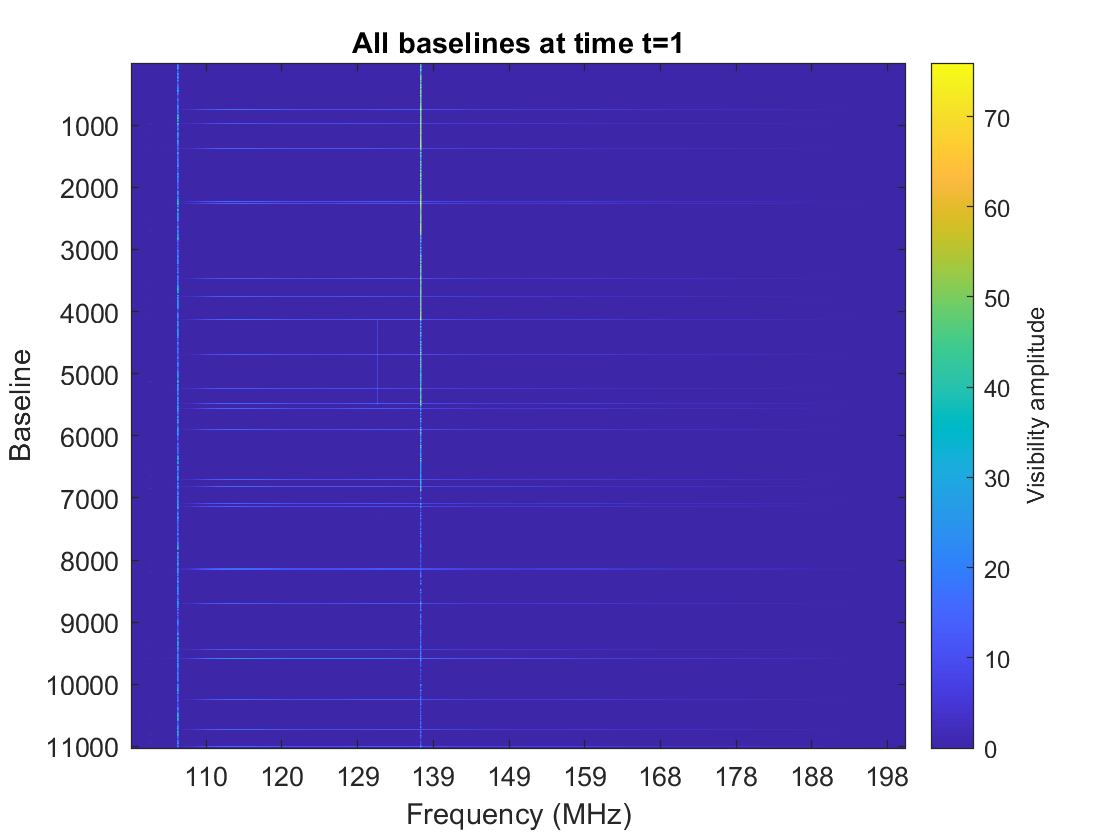

%Just work with XY polarization first:
pol = 2;
range = 1:1378*8;
visdata_re = visdata.r(pol, :, 1, range);
visdata_im = visdata.i(pol, :, 1, range);
visdata_magnitude = sqrt(visdata_re.^2 + visdata_im.^2);
visdata_time1 = visdata_magnitude(:, :, 1, range);

clf;
imagesc(squeeze(visdata_time1)')
xt = get(gca, 'XTick');
set(gca, 'XTick', xt, 'XTickLabel', round(xt/10.24 + 100));
xlabel('Frequency (MHz)');
ylabel('Baseline')
c = colorbar;
c.Label.String = "Visibility amplitude";
title('All baselines at time t=1')

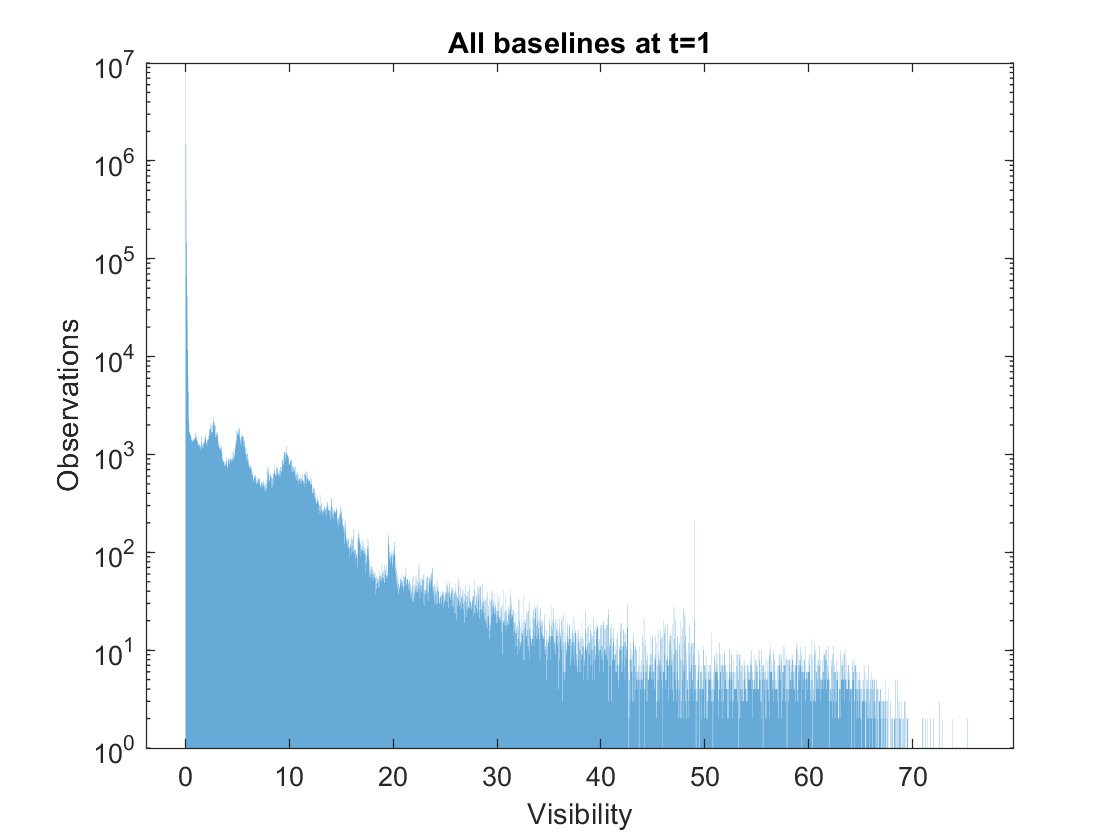

clf;
histogram(visdata_time1, 'EdgeColor',"none")
set(gca, 'YScale', 'log')
ylabel('Observations')
xlabel('Visibility')
title('All baselines at t=1')

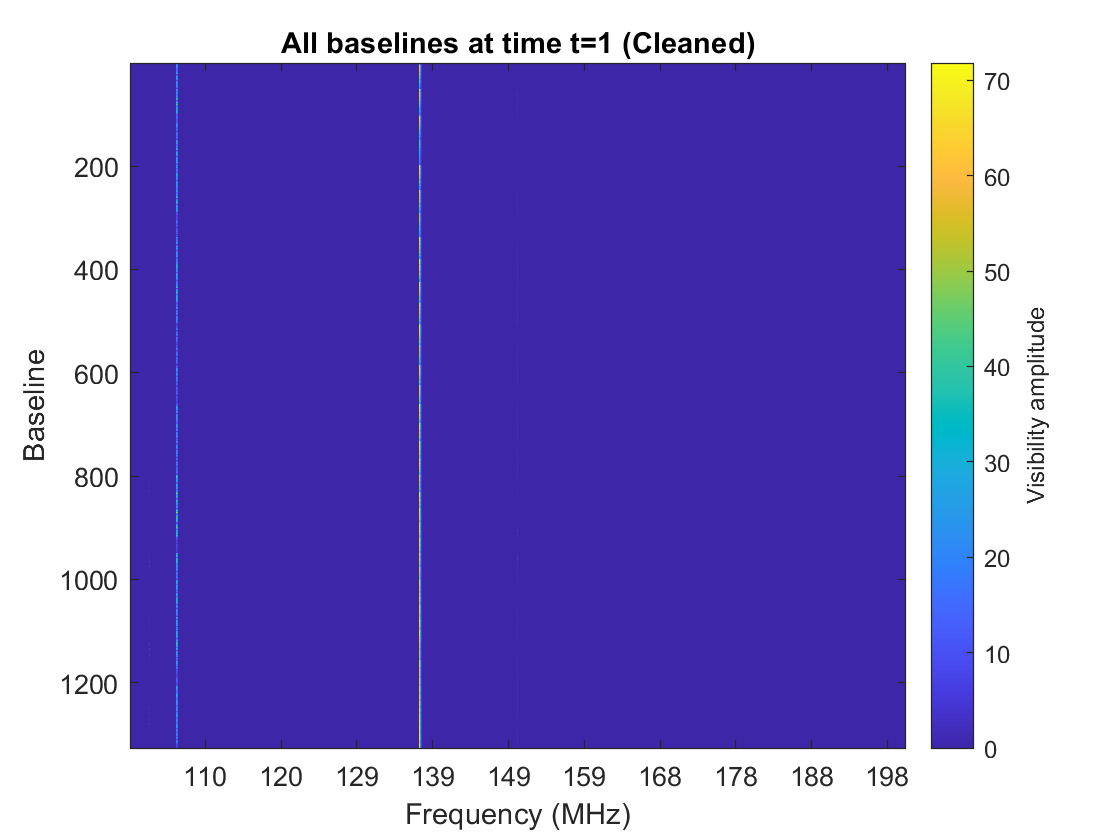

commonpair_indices = baselines(:, 1) == baselines(:, 2);
clean_data = visdata_time1(:, :, :, ~commonpair_indices);

clf;
clean_img = squeeze(clean_data)';
imagesc(clean_img)
xt = get(gca, 'XTick');
set(gca, 'XTick', xt, 'XTickLabel', round(xt/10.24 + 100));
xlabel('Frequency (MHz)');
ylabel('Baseline')
c = colorbar;
c.Label.String = "Visibility amplitude";
title('All baselines at time t=1 (Cleaned)')

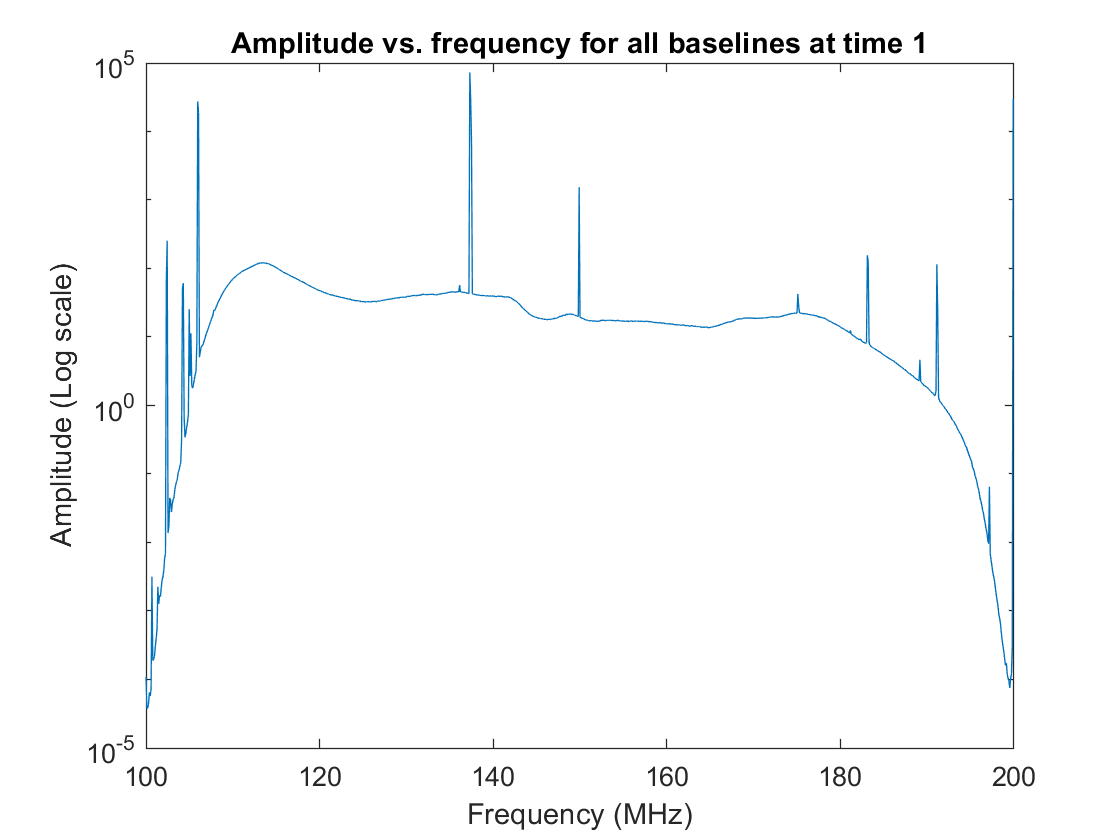

amplitude1 = squeeze(sum(clean_img, 1));
clf;
semilogy(freq_array ./ 1e6, amplitude1(1:1024))
xlabel('Frequency (MHz)');
ylabel('Amplitude (Log scale)')
title('Amplitude vs. frequency for all baselines at time 1')

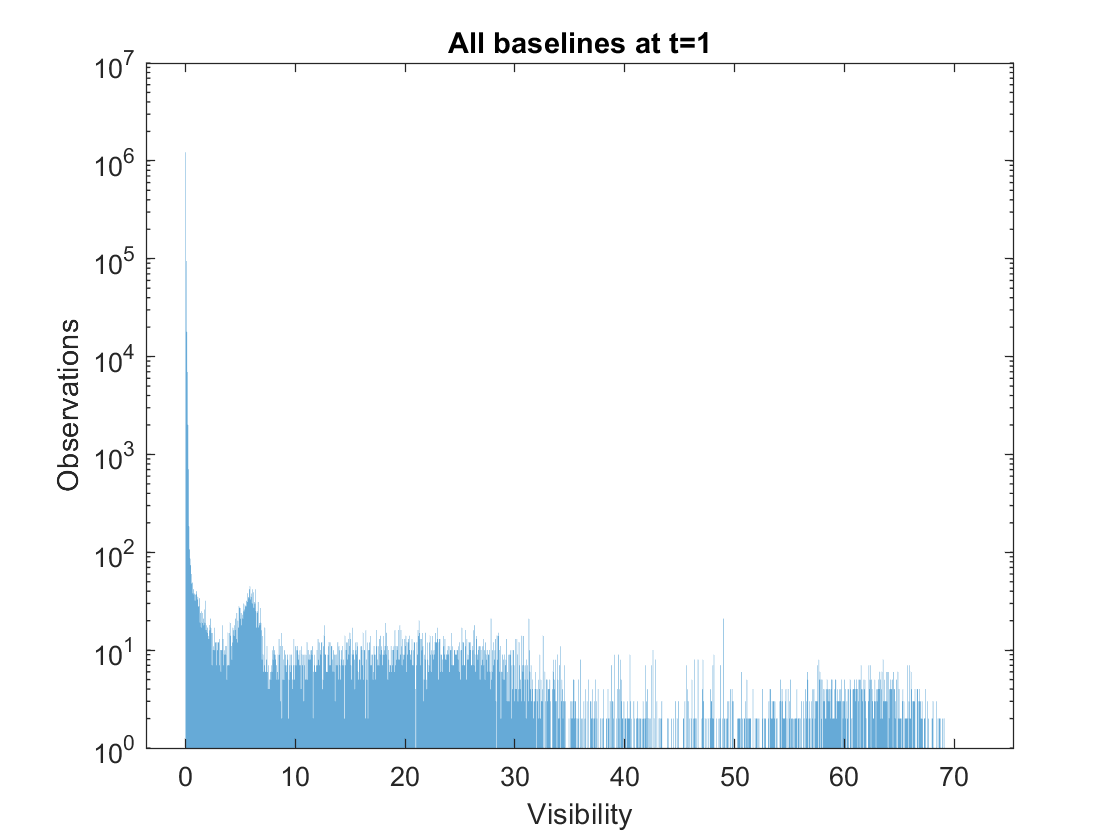

clf;
histogram(clean_img, 'EdgeColor',"none")
set(gca, 'YScale', 'log')
ylabel('Observations')
xlabel('Visibility')
title('All baselines at t=1')

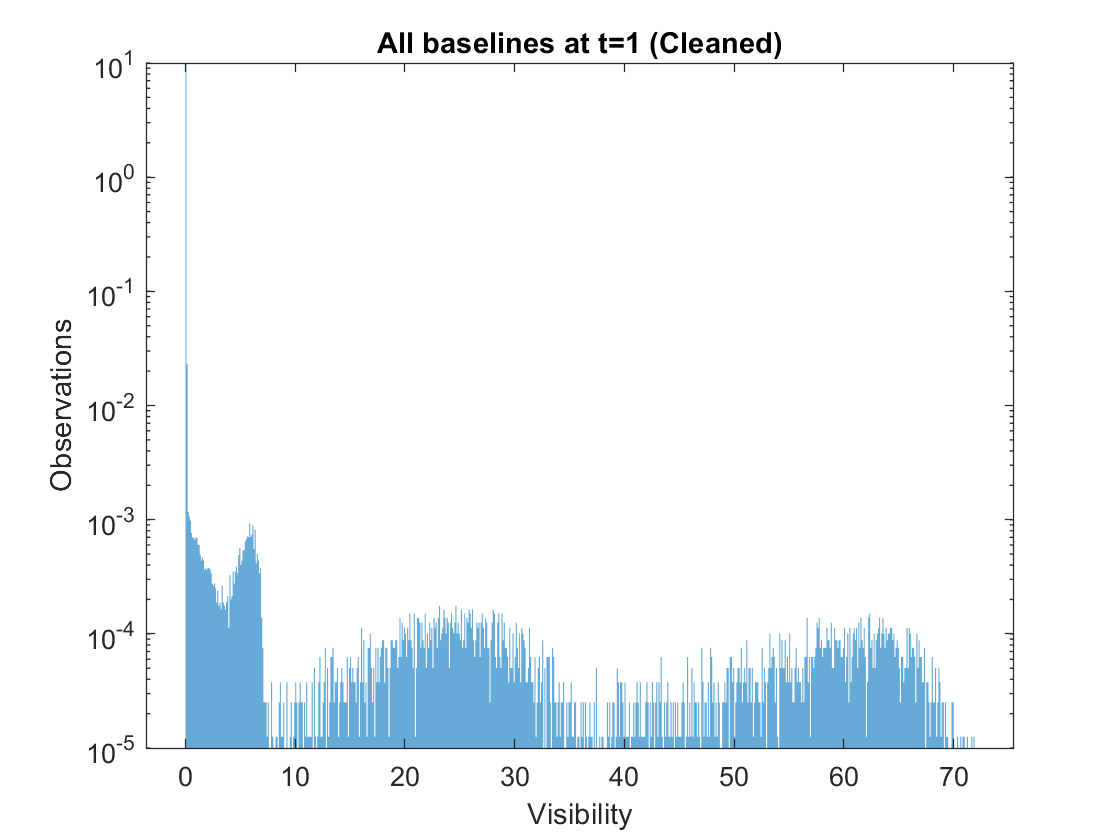

clf;
clean_data_limit = clean_img(:, 200:800);
histogram(clean_data_limit, 'EdgeColor',"none", 'Normalization', 'pdf')
set(gca, 'YScale', 'log')
ylabel('Observations')
xlabel('Visibility')
title('All baselines at t=1 (Cleaned)')

clf;
bkg_limit = 0.2;
bkg = clean_data_limit(abs(clean_data_limit) < bkg_limit);
histogram(bkg, 100, 'EdgeColor',"none", 'Normalization', 'pdf'), hold on;
fit_xs = linspace(0, bkg_limit, 1000);
PD = fitdist(reshape(clean_data_limit, 1, [])', 'Lognormal')

PD =   LognormalDistribution

  Lognormal distribution
       mu = -4.13175   [-4.13381, -4.12969]
    sigma = 0.937629   [0.936175, 0.939086]


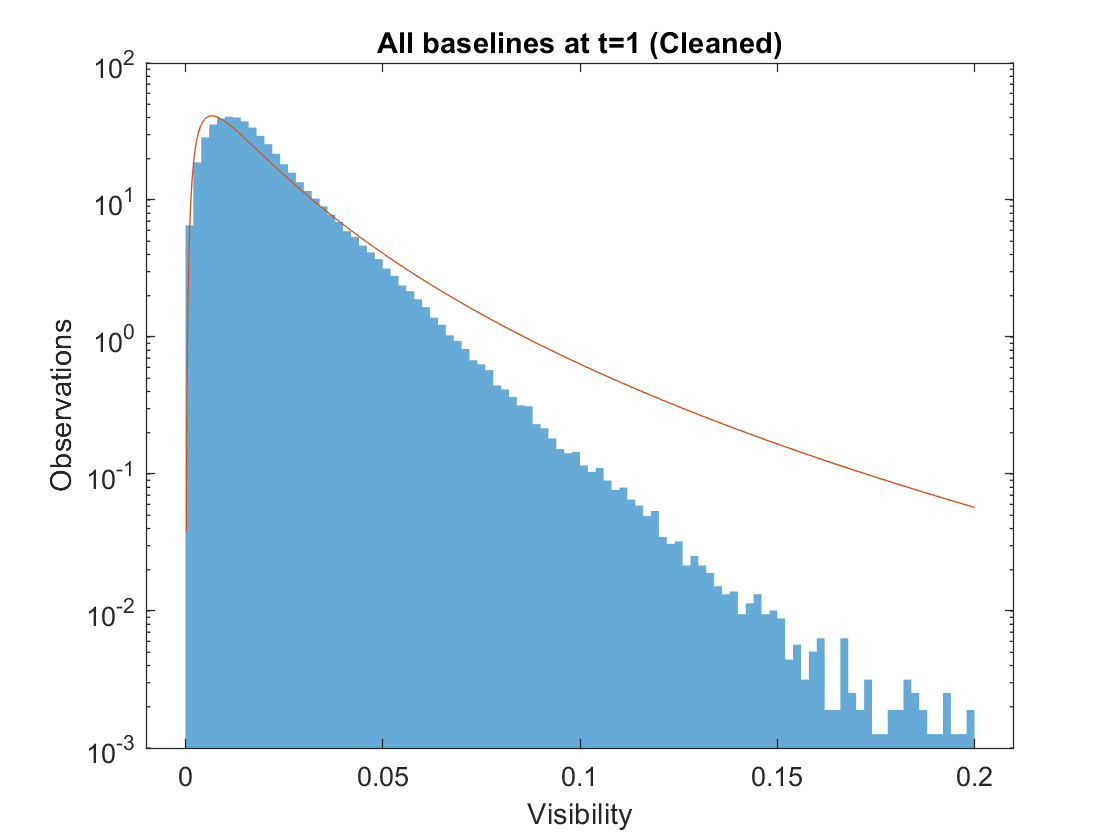

mu = PD.mu;
sigma = PD.sigma;
fit_ys = lognpdf(fit_xs, mu, sigma);
plot(fit_xs, fit_ys)
set(gca, 'YScale', 'log')
ylim([1e-3 1e2])
ylabel('Observations')
xlabel('Visibility')
title('All baselines at t=1 (Cleaned)')

p_norm = normcdf(-5, 0, 1)

p_norm = 2.8665e-07

threshold = icdf('Lognormal', 1-p_norm, mu, sigma)

threshold = 1.7444

### Problem 2

p_norm = normcdf(-8, 0, 1)

p_norm = 6.2210e-16

signal = icdf('Lognormal', 1-p_norm, mu, sigma)

signal = 28.8290

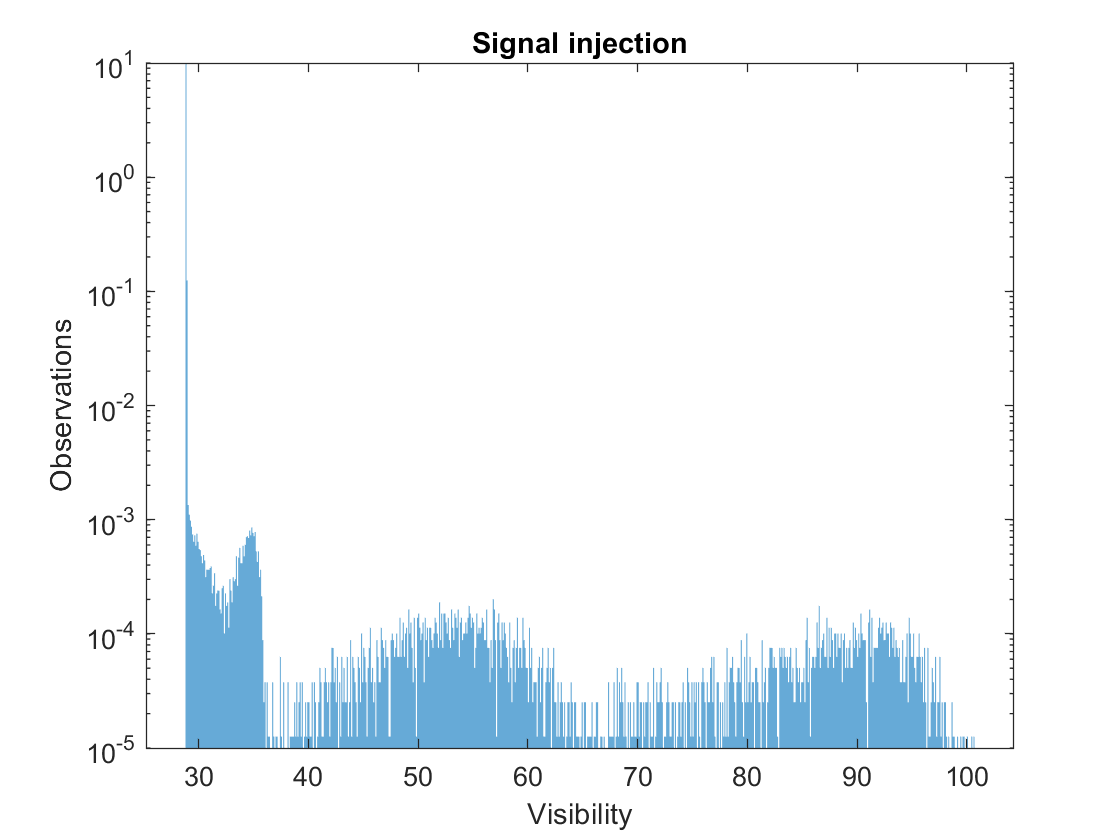

indices = (randi(10, [1326, 600]) < 11);
signal_injection = signal .* indices;
data_array = clean_img(:, 201:800);
clf;
histogram(data_array + signal_injection, 'EdgeColor',"none", 'Normalization', 'pdf')
set(gca, 'YScale', 'log')
ylabel('Observations')
xlabel('Visibility')
title('Signal injection')

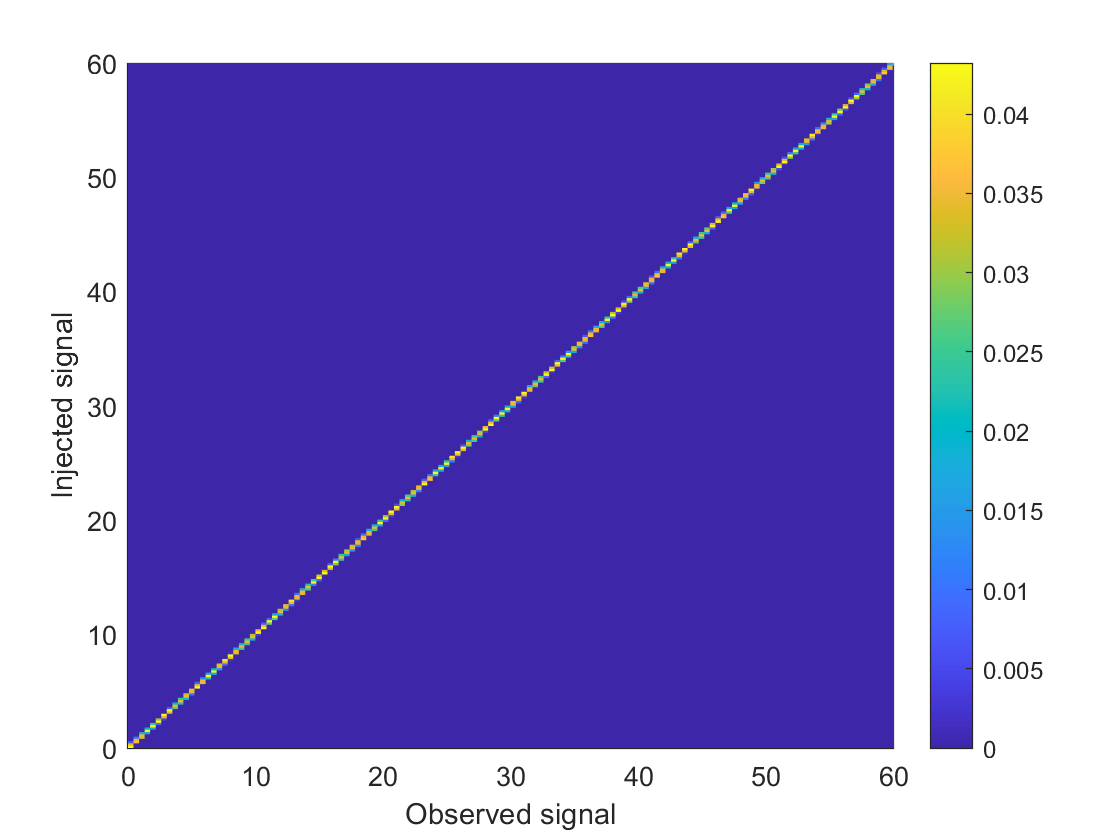

s_lim = 60;
signal_suite = linspace(0, s_lim, 1326);
[~, signal_array] = meshgrid(signal_suite);

noise = indices .* data_array;
obssignal = noise + signal_array(1:1326, 1:600);

clf;
h = histogram2(obssignal,signal_array(1:1326, 1:600), 300,'DisplayStyle','tile','ShowEmptyBins','on', 'Normalization', 'pdf');
xlabel('Observed signal');
ylabel('Injected signal');
axis([0 s_lim 0 s_lim])
c = colorbar;